# **Excercise 2: Principal Component Analysis (PCA)**

The aim of this excercise is to apply principal component analysis to our real estate dataset and cluster the data with the first three principal components.

## ***Abstract***

*In this task, the data from task 1 is reduced to three dimensions using PCA. The clustering is minimally different and a different number of cluster turned out to be optimal, but the data can be visualized more easily.*

% Initialization
clear ; close all; clc 

% Set default image size
set(groot,'defaultfigureposition',[600 250 400 250]) 

## **Develop toolset**

In the following sections we develop different functions which are needed for principal component analysis.

### Generate dev data

The data used for the development is generated using the *generate2DData.m *function we used already in excercise 1. The generated data scatter by 3 points - for the classification therefore k = 3 is expected as the optimal number of clusters. Compared to the previous task, fewer data points were created. This is due to the fact that the effects of dimension reduction are better recognizable. Below the first five rows will be displayed:

% Generate dev data
X = generate2DData;

% Print example values
disp(X(1:5, :))

   1.514398241786709   0.911906409124758
   1.944811900458953   0.852092039152804
   3.538868950696287   1.302514271207917
   0.054232068165518   1.981541060067632
   1.609223211287189   3.554987246014842



### Normalize features

To use principal component analysis the features have to be normalized to a similar scale.

% Normalize features
[X_norm, mu, sigma] = featureNormalize(X);

### Run PCA

After we have normalized the features, we can calculate the principal components:

% Run PCA
[U, S] = pca(X_norm);

We now plot the eigenvectors centered at mean of data. These lines show the directions of maximum variations in the dataset.

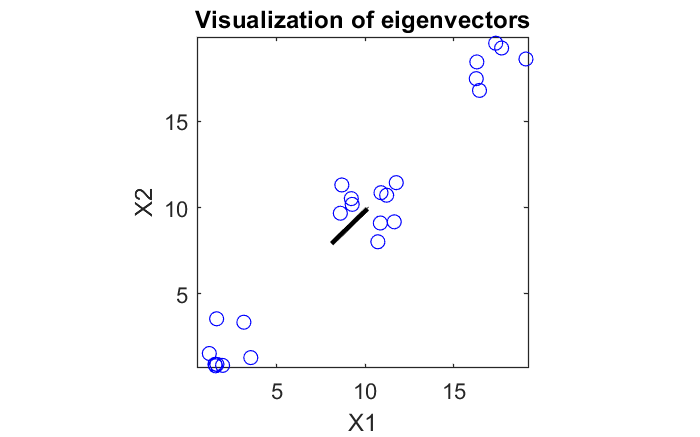

% Plot principal components
plotPrincipalComponents(X, U, S, mu)

### Reduce dimensions

After computing the principal components, we can use them to reduce the feature dimension of our dataset by projecting each example onto a lower dimensional space. To get an idea of the behaviour we set K = 1. The plot below shows, that all the data points are projected onto an 1D line (for a better representation, only the axis section of the middle data group is displayed).

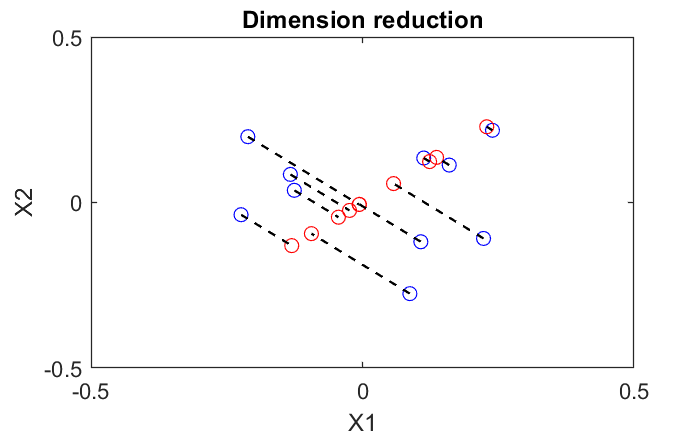

%  Project the data onto K = 1 dimension
K = 1;
Z = projectData(X_norm, U, K);
X_rec  = recoverData(Z, U, K);

% Plot dimension reduction
plotReducedDimensions(X_norm, X_rec);

### Choosing the value of K

To get an idea of a suitable number of clusters, we use again our different methods to determine the optimal value of k.

#### Elbow method

In an "elbow" plot whe show the distortion for *2 ≤ k ≤ 20. *According to the plot, around three clusters would be optimal:

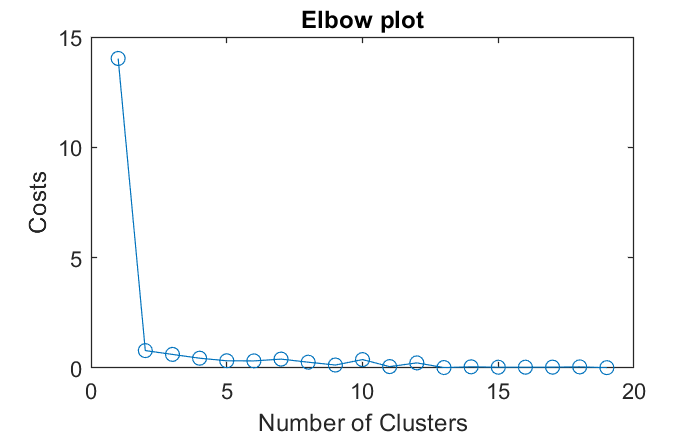

% Settings for running K-means
max_iters = 10;

% Visualize elbow plot
visualizeDistortion(X_rec, max_iters)

#### Silhouette method

The silhouette plot provides a slightly more specific value. We calculate the silhouette values again for *2 ≤ k ≤ 20. *Again, we retrieve a value around three for the optimal number of clusters:

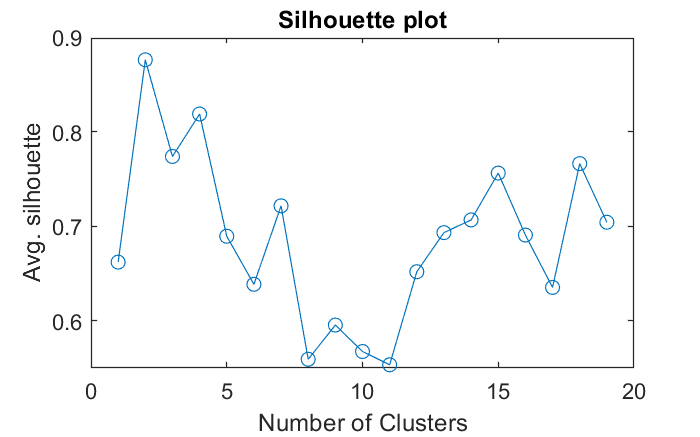

% Visualize silhouette plot
visualizeSilhouette(X_rec, max_iters)

#### Gap statistic*

Another method is the gap statistics. We use the implementation of *evalclusters* to get an additional clue for an optimal k and to verify the functionality of the other two methods.

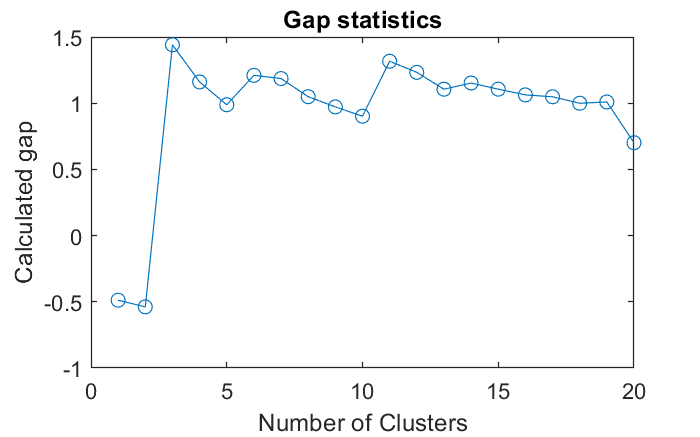

% Visualize gap statistics
visualizeGapStatistic(X_rec)

This verification confirms our previous findings - we will therefore choose three as the number of our clusters.

### Initialize parameters

In the following sections, we set our K-means settings. The above tests have all shown that three different clusters deliver the best values. The initial centroids are initialized randomly but at most 10 times.

% Settings for running K-means
K = 3; 
max_iters = 10;
max_inits = 10;

### Cluster data

As our parameters are initialized we can iteratively find the closest neighbours and compute the means to get a proper clustering. The process of clustering the data is shown in a plot. The course of the centroids approximation is thereby displayed as Xes, which are connected with coloured lines. The visualization confirms that the choice of three clusters makes sense, as the data is clearly separated.

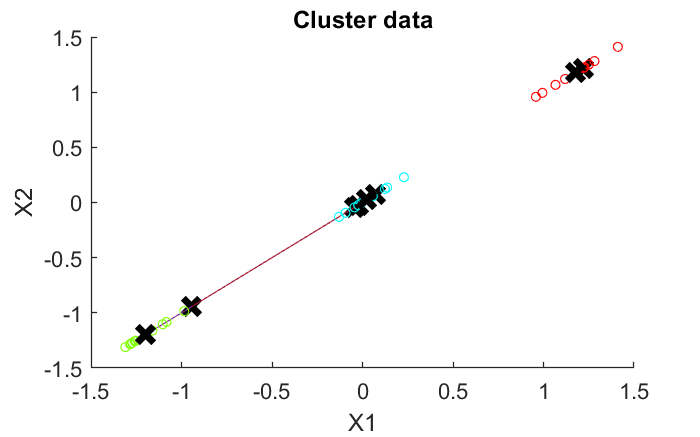

% Cluster data
[centroids, idx, J] = clusterData(X_rec, K, max_inits, max_iters, true);

### Analyze clusters

Below we characterize the three clusters formed. We calculate variance, mean value, minimum and maximum for the two most similar features per cluster:

% Define column names
keySet = {1, 2};
valueSet = {'X1', 'X2'};
column_header = containers.Map(keySet,valueSet);

% Characterize cluster
n = 2; % Use top 2 similar features
characteriseCluster(X, idx, K, n, column_header)

Most similar features
Cluster 1, (0.33 amount of total data)
  - X2, (var: 1.46, avg: 18.12, min: 16.14, max: 19.70)
  - X1, (var: 2.11, avg: 18.13, min: 16.28, max: 19.79)
Cluster 2, (0.33 amount of total data)
  - X2, (var: 1.14, avg: 1.58, min: 0.61, max: 3.55)
  - X1, (var: 1.21, avg: 1.96, min: 0.05, max: 3.54)
Cluster 3, (0.33 amount of total data)
  - X2, (var: 1.20, avg: 10.11, min: 8.02, max: 11.45)
  - X1, (var: 1.48, avg: 10.29, min: 8.60, max: 11.76)


Similar, to the first excercise following properties result from the values calculated above:

- **Cluster 1, 33%: **High values for X1 and X2 - well recognizable by average and min/max

- **Cluster 2, 33%: **Medium values for X1 and X2 - again, well recognizable by average and min/max

- **Cluster 3, 33%: **Low values for X1 and X2 as we can see on average and min/max

## **Cluster house data**

In this part of the excercise, the principal component analysis will be applied to our clustered house data.

### Load house data

The data will again be read from the file *house_data*`.csv`. Below the first five rows will be displayed:

% Load house data
house_data = importHouseData('house_data.csv', 5);

ans = 5×19 table
    build_year          lat           living_area          long            municipality_name      zipcode    num_rooms    object_type_name    price     water_percentage_1000    travel_time_private_transport    travel_time_public_transport    number_of_buildings_in_hectare    number_of_apartments_in_hectare    number_of_workplaces_in_hectare    number_of_workplaces_sector_1_in_hectare    number_of_workplaces_sector_2_in_hectare    number_of_workplaces_sector_3_in_hectare    population_in_hectare
    __________    ________________    ___________    ________________    ___________

We'll use the same features we used already in excercise 1.

% Initialize variables
X = double(table2array(house_data(:, [{'price'},
                                      {'travel_time_private_transport'},
                                      {'number_of_workplaces_in_hectare'},
                                      {'number_of_workplaces_sector_1_in_hectare'},
                                      {'number_of_workplaces_sector_2_in_hectare'},
                                      {'number_of_workplaces_sector_3_in_hectare'},
                                      {'population_in_hectare'}])));

### Normalize features

The use of discrete features (e.g.* number_of_workplaces_in_hectare*) on a scale is limited because K-means assumes a continuous distribution here as well. To avoid this circumstance, we normalize the features as we did already in excercise 1.

% Normalize features
[X_norm, mu, sigma] = featureNormalize(X);

### Run PCA

After we have normalized the features, we can calculate the principal components:

% Run PCA
[U, S] = pca(X_norm);

### Reduce dimensions

Now we can use the principal components to reduce the feature dimension of our dataset by projecting each example onto a lower dimensional space. As de data is reduced to three dimensions, it can easily be visualized in 3D:

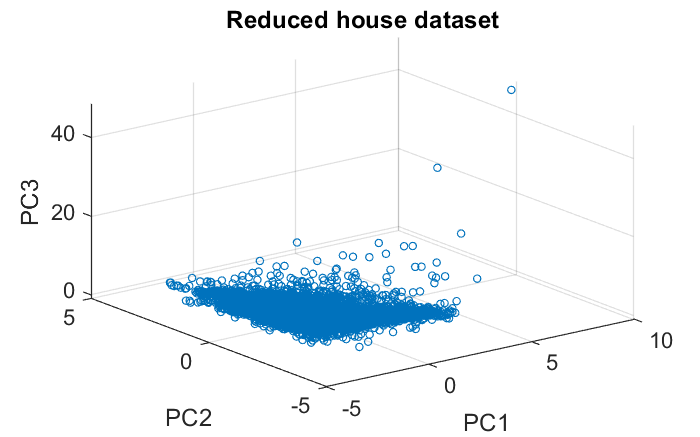

%  Project the data onto K = 3 dimension
K = 3;
Z = projectData(X_norm, U, K);
X_rec  = recoverData(Z, U, K);

%  Visualize the reduced data in 3D
figure;
scatter3(X_rec(:, 1), X_rec(:, 2), X_rec(:, 3), 10);
title('Reduced house dataset');
xlabel('PC1')
ylabel('PC2')
zlabel('PC3')

### Choosing the value of K

To get an idea of a suitable number of clusters, we plot the distortion for *2 ≤ k ≤ 20. *With this lower-dimensional dataset, the elbow plot is less clear. Based on the plot it can be guessed that k should be in the range `[3, 6]`:

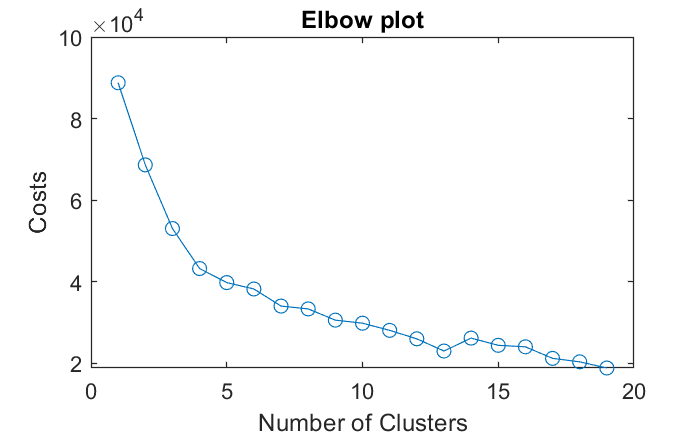

% Settings for running K-means
max_iters = 10;

% Visualize elbow plot
visualizeDistortion(X_rec, max_iters)

We again use the silhouette plot to get more detailed information about the optimal k. Based on the two plots we choose 4 as the number of clusters.

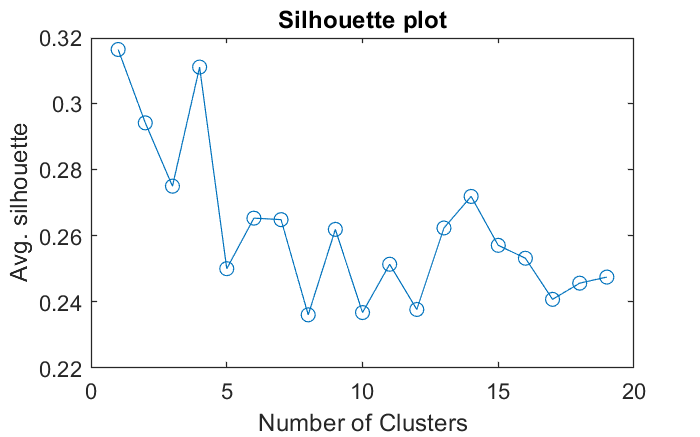

% Visualize silhouette
visualizeSilhouette(X_rec, max_iters)

### Initialize parameters

In the following sections, we set our K-means settings. As explained above, we form four clusters. The initial centroids are again initialized randomly multiple times:

% Settings for running K-means
K = 4; 
max_iters = 20;
max_inits = 10;

### Cluster data

With our reduced dataset we can iteratively find the closest neighbours and compute the means to get a proper clustering:

% Cluster data
[centroids, idx, J] = clusterData(X_rec, K, max_inits, max_iters, false);

### Visualize clusters 

Again, whe plot the clusters on a map. 

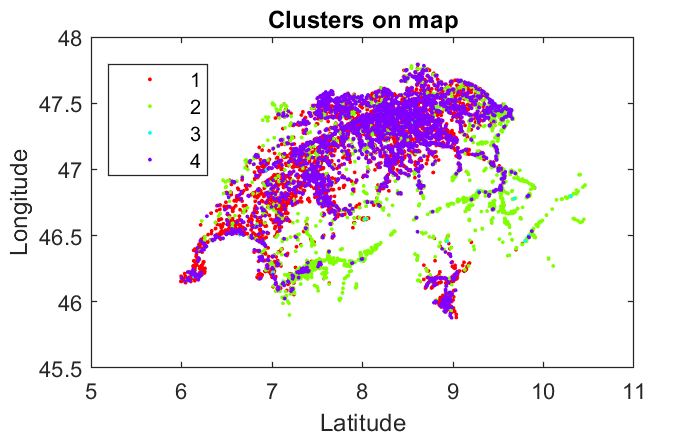

% Load geo information
X_geo = double(table2array(house_data(:, [{'lat'},
                                          {'long'}])));
            
% Plot map  
plotMap(X_geo, idx,'Clusters on map')

Since we have reduced the features to three, we can additionally display the clusters in 3-dimensional space: 

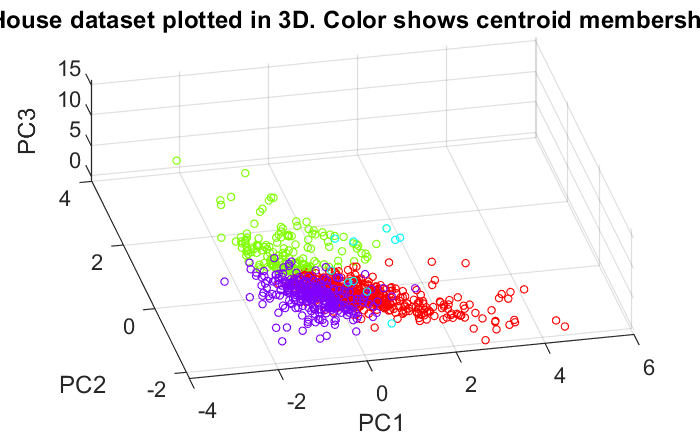

% Plot 3D data points
plot3DDataPoints(X_rec, idx, K)

### Analyze clusters

Again calculate variance, mean value, minimum and maximum for the three most similar features per cluster:

% Define column names
keySet = {1, 2, 3, 4, 5, 6, 7};
valueSet = {'price',
            'travel_time_private_transport',
            'number_of_workplaces_in_hectare',
            'number_of_workplaces_sector_1_in_hectare',
            'number_of_workplaces_sector_2_in_hectare', %
            'number_of_workplaces_sector_3_in_hectare',
            'population_in_hectare'};
column_header = containers.Map(keySet,valueSet);

% Print cluster characteristics
n = 3; % Use top 3 similar features
characteriseCluster(X_norm, idx, K, n, column_header)

Most similar features
Cluster 1, (0.52 amount of total data)
  - number_of_workplaces_sector_1_in_hectare, (var: 0.03, avg: -0.23, min: -0.24, max: 4.10)
  - number_of_workplaces_in_hectare, (var: 0.12, avg: -0.28, min: -0.63, max: 1.88)
  - number_of_workplaces_sector_3_in_hectare, (var: 0.13, avg: -0.23, min: -0.58, max: 2.09)
Cluster 2, (0.17 amount of total data)
  - number_of_workplaces_sector_3_in_hectare, (var: 0.23, avg: -0.15, min: -0.58, max: 3.43)
  - number_of_workplaces_in_hectare, (var: 0.23, avg: -0.08, min: -0.63, max: 3.34)
  - population_in_hectare, (var: 0.30, avg: -0.48, min: -1.09, max: 4.30)
Cluster 3, (0.01 amount of total data)
  - travel_time_private_transport, (var: 1.38, avg: -0.42, min: -1.47, max: 4.58)
  - price, (var: 1.40, avg: 0.20, min: -1.27, max: 5.14)
  - number_of_workplaces_sector_1_in_hectare, (var: 2.05, avg: 0.25, min: -0.24, max: 6.99)
Cluster 4, (0.29 amount of total data)
  - number_of_workplaces_sector_1_in_hectare, (var: 0.04, avg: -0.23, 

The following properties result from the values calculated above:

- **Cluster 1, 52%: **Cluster 1 is characterised by a low number of workplaces in hectare. This is underlined by the low number of jobs in the first two sectors.

- **Cluster 2, 17%:** These properties have the small number of inhabitants in the surrounding area in common. On the map you can quickly see that these are mainly rural regions.

- **Cluster 3, 1%:** The properties in this group are characterised by a short distance to private transport and a high price. On the map we can see that these objects are close to (or in) cities as Geneva, Basel, Zurich, etc.

- **Cluster 4, 29%:** In contrast to the first cluster, we see a high number of jobs in this cluster. Nevertheless, property prices are below average.

#### Disscuss the differences between the clusters of excercise 1) and excercise 2)

PCA was used in excercise 2), while data was clustered directly in excercise 1). The following pictures show the clustering of excercise 1 (left) and the one of excercise 2 (right).

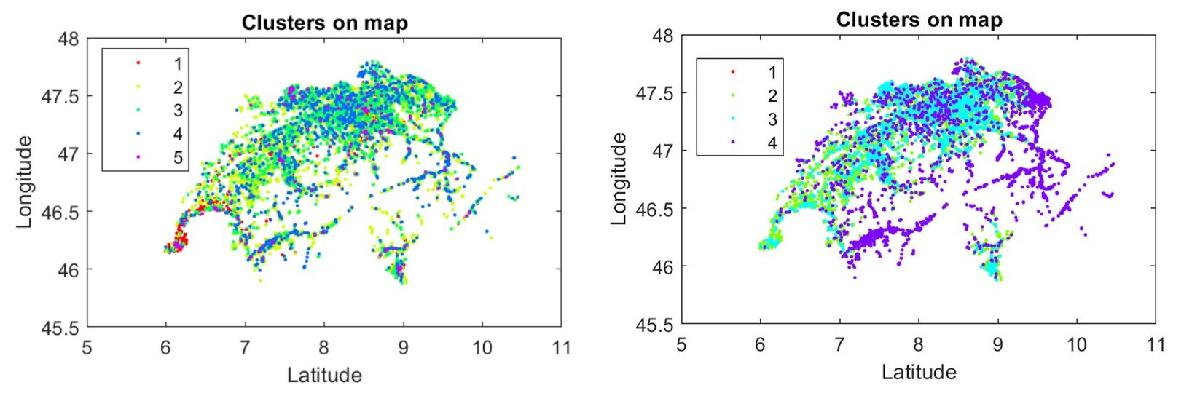

The fact that the clustering with PCA suggested four instead of five clusters shows quite obviously that the data was not grouped exactly the same way. When using PCA data is reduced to lower dimensions. This has the advantage, that less data and ressources are needed. Calculation therefore takes not as long as when running without PCA and more dimensions. Moreover when using only three dimensions or less, the clustered data can be visualized in a easy understandable manner. Howewer, with the reduction information gets lost and the data can not be grouped in the same granularity.

When comparing the carasteristics of the clusters we can see, that in excercise 1) mainly the features concering number of workplaces in the different sectors were used. In the variant with pca, however, further features such as *population_in_hectare *or *travel_time_private_transport* were used for cluster formation.

For comparison purposes we run the clustering of excercise 1) again without  PCA but this time using four clusters. However, the differences between the various clusters (without PCA left, with PCA right) are still visible:

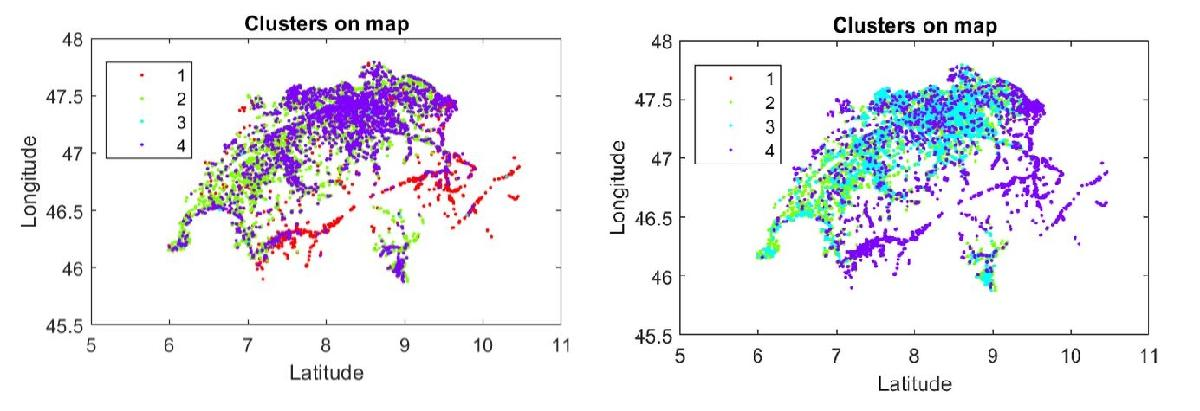

#### Visualize the first 3 principal components and discuss properties that could negatively impact clustering

The top three principal components have already been plotted in an earlier section (see *Visualize clusters*). In general feature choice has a big impact on how well the clustering will be. Categorical features can not be considered and also the use of discrete features (e.g.* number_of_workplaces_in_hectare*) on a scale is limited because K-means assumes a continuous distribution here as well. To avoid this circumstance, the features should be normalized.

#### Is it enough to use only the first 3 principal components?

In general there is always a trade-off between information and ressources. On the one hand, as much information as possible should be taken into account. On the other hand, reduction to fewer dimensions brings advantages in terms of performance and better visualization possibilities. Different runs without PCA but using many features have also shown that with too many features the clustering is less good.

In this case three principal components seems to be a good choice. Howewer, when using more features it should be considered to use more than those three principal components as well.